Test how two multinomial distributions combine

clc;
clear variables;
close all;

Nsamples = 1000;


Distribution 1

x = [-0.5,0.5];

nIntSteps = 4;
intFun = @(y) trapz(normpdf(linspace(y(1),y(2),nIntSteps),y(3),y(4)))*(y(2)-y(1))/(nIntSteps-1); % For particle count

log_radii =[-1.38629436111989
-1.04982212449868
-0.693147180559945
0.405465108108164
0.916290731874155
1.60943791243410
2.52572864430826];

probs = [];
for k=1:size(log_radii,1)-1
    probs = [probs, intFun([log_radii(k),log_radii(k+1),x])];
end


% Ues only some dims
probs = probs/sum(probs);

P = diag(probs);
M = P - probs'*probs;

n = 2e6;

mu = n*probs;
cov_mat = n*M;

samples1 = mvnrnd(mu,cov_mat,Nsamples);

Distribution 2

x2 = [0,0.5];

probs2 = [];
for k=1:size(log_radii,1)-1
    probs2 = [probs2, intFun([log_radii(k),log_radii(k+1),x2])];
end


% Ues only some dims
probs2 = probs2/sum(probs2);

P2 = diag(probs2);
M2 = P2 - probs2'*probs2;

n2 = 1*n;
mu2 = n2*probs2;
cov_mat2 = n2*M2;
%cov_mat2 = 0.5*(cov_mat2 + cov_mat2');

samples2 = mvnrnd(mu2,cov_mat2,Nsamples);


Difference

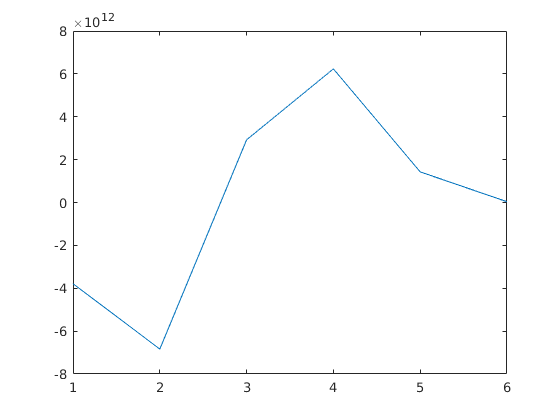

diff_mat = samples2 - samples1;

mu_diff = mean(diff_mat,1);
cov_diff = cov(diff_mat);

n_est = sum(mu_diff);
probs_est = mu_diff/n_est;

plot(probs_est)